# DeepLearning

clases = cell(100, 1);
clases(1:58) = {'Alto'};
clases(59:90) = {'Moderado'};
clases(91:98)={'Aficionado'}

clases = 100×1 cell array
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}


clases(99:100)={'Falla cardiaca'}

clases = 100×1 cell array
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}
    {'Alto'}


# Neurona

Función de activación por defecto: tangencial. Red con 4 capas ocultas, en la que el tamaño de la primera capa oculta es 5, el de la segunda es 8 y el de la tercera es 4.

neuro=fitnet([10 8 8 10])

neuro =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 5
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 260
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1; 1]
      

a =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


b =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


c =      3
     3
     3
     3
     3
     3
     3
     3


d =      4
     4


clasesN =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


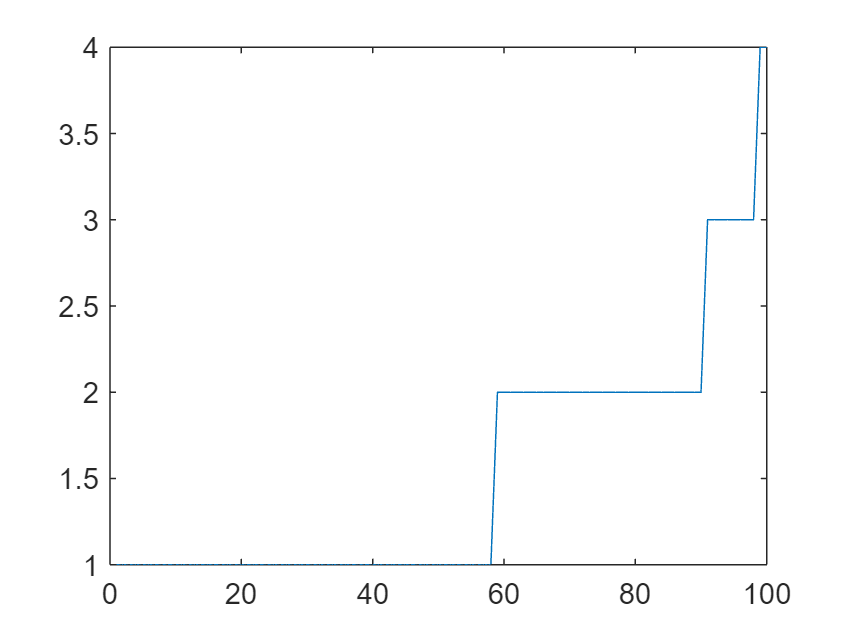

a=ones(58,1)
b=ones(32,1)*2
c=ones(8,1)*3
d=ones(2,1)*4
clasesN=[a;b;c;d]
plot(clasesN)

### Datos de entrenamiento y prueba

dataEntr2=data;
clasesEntr2= clasesN;
dataPr2=data;
clasesPr2=clasesN;

clasesEntr2(1:16)=[];
clasesEntr2(41:50)=[];
clasesEntr2(67:70)=[];
% %clasesEntr2(70)=[];

dataEntr2(1:16,:)=[];
dataEntr2(41:50,:)=[];
dataEntr2(67:70,:)=[];
%dataEntr2(70,:)=[];

%30 elementos de prueba
clasesPr2(16:59)=[];
clasesPr2(25:48)=[];
clasesPr2(25:26)=[];
% clasesPr2(31)=[];
 
dataPr2(16:59,:)=[];
dataPr2(25:48,:)=[];
dataPr2(25:26,:)=[];
%dataPr2(31,:)=[];

neuro=train(neuro,dataEntr2',clasesEntr2');
%obtener los datos
resred2=round(sim(neuro,dataPr2'));
plot(resred2)

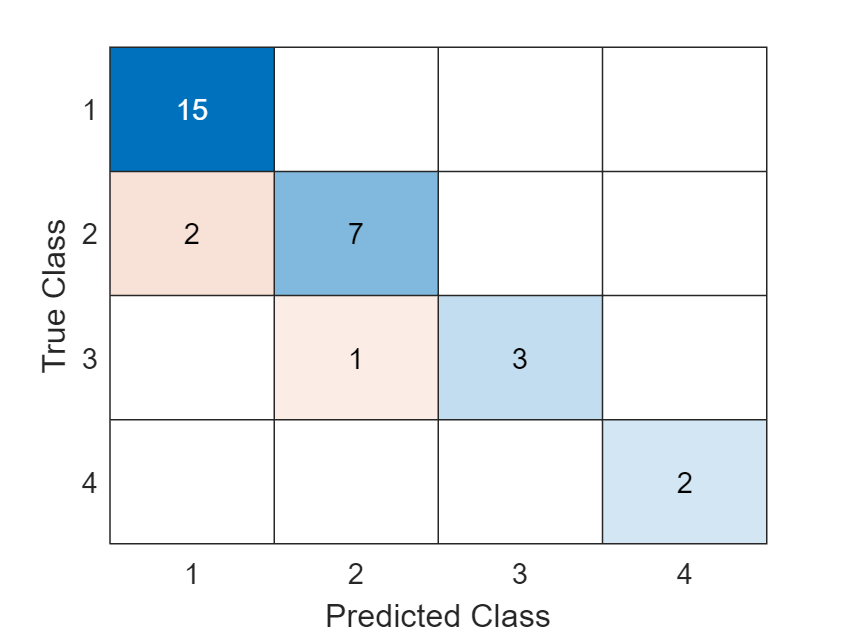

confusionchart(clasesPr2,resred2)

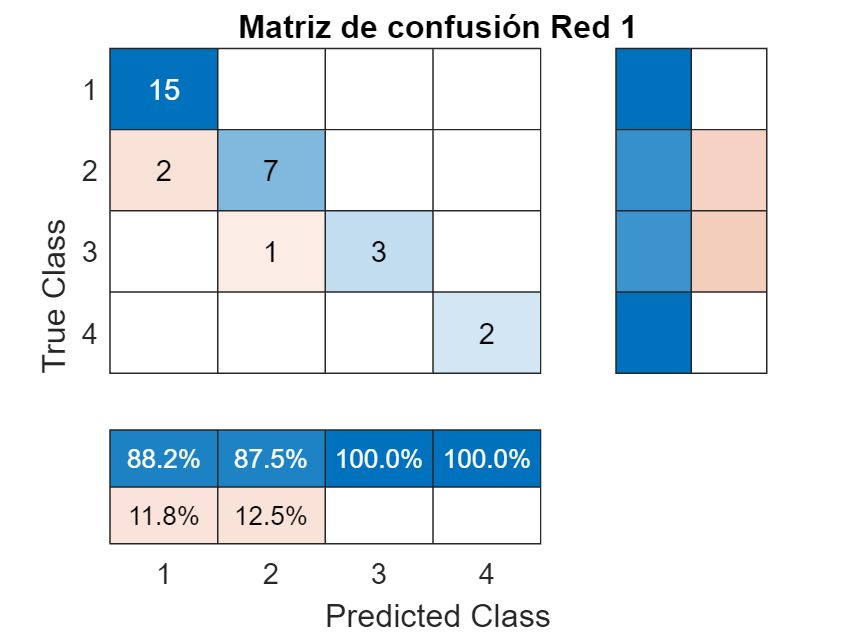

%matriz de confusion
confusionchart(clasesPr2,resred2,'ColumnSummary','column-normalized','RowSummary','row-normalized','Title','Matriz de confusión Red 1')

# Árbol

dataEntr=data;
clasesEntr= clases;
dataPr=data;
clasesPr=clases;

clasesEntr(1:16)=[];
clasesEntr(41:50)=[];
clasesEntr(67:70)=[];
% %clasesEntr2(70)=[];

dataEntr(1:16,:)=[];
dataEntr(41:50,:)=[];
dataEntr(67:70,:)=[];
%dataEntr2(70,:)=[];

%30 elementos de prueba
clasesPr(16:59)=[];
clasesPr(25:48)=[];
clasesPr(25:26)=[];
% clasesPr2(31)=[];
 
dataPr(16:59,:)=[];
dataPr(25:48,:)=[];
dataPr(25:26,:)=[];
%dataPr2(31,:)=[];

#### Entrenar un árbol de desición con clasesEntr y dataEntr

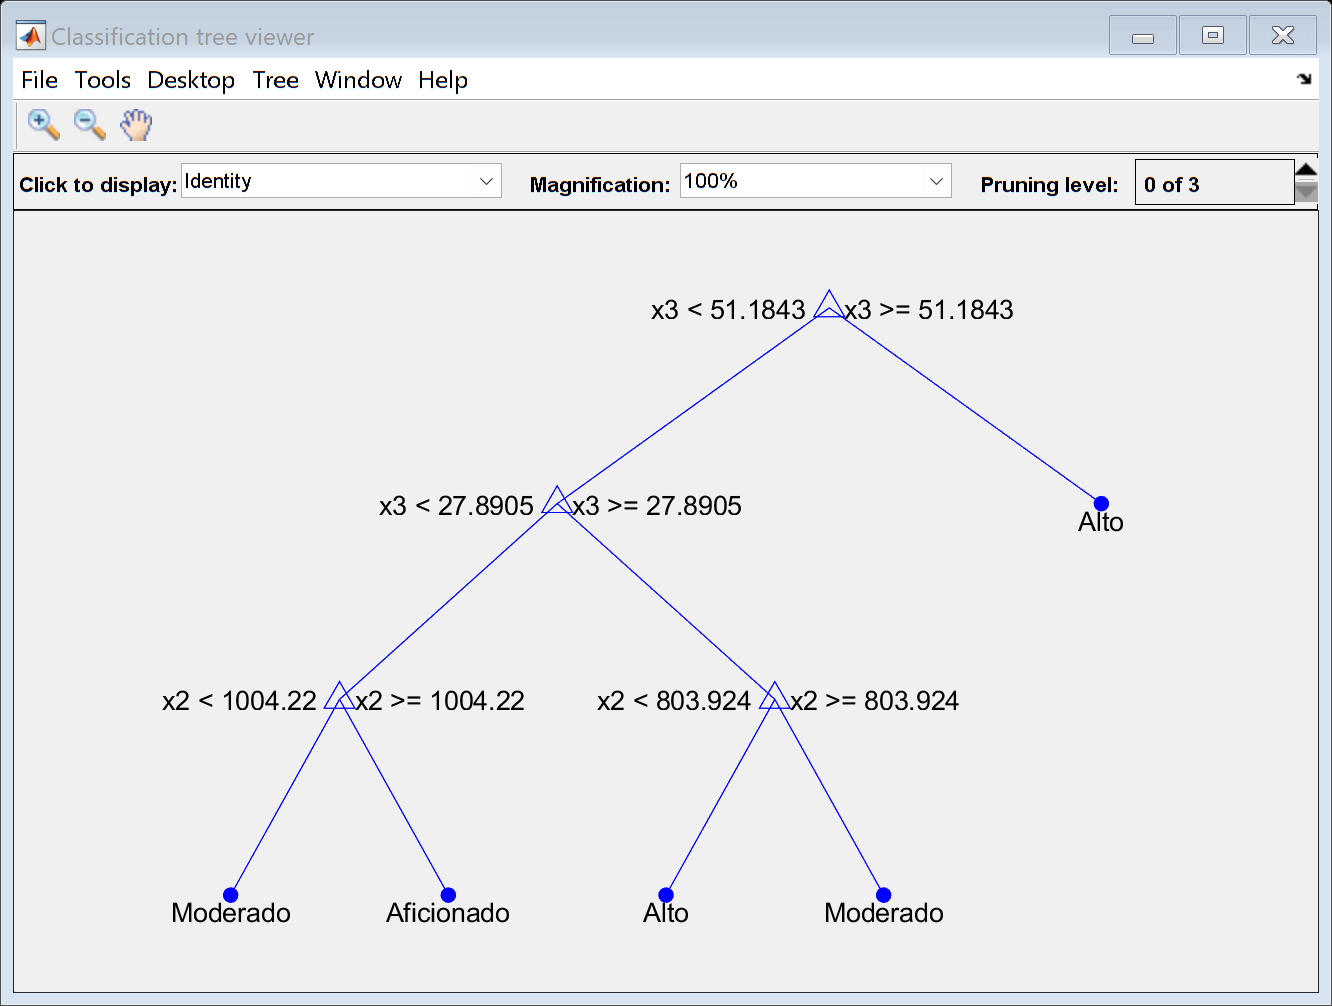

palmera=fitctree(dataEntr,clasesEntr);
view(palmera,'Mode','graph');

#### Probar el modelo de árbol de decisión obtenido con res-dataPr

result=predict(palmera,dataPr);
result

result = 30×1 cell array
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Alto'      }
    {'Moderado'  }
    {'Moderado'  }
    {'Moderado'  }
    {'Moderado'  }
    {'Moderado'  }
    {'Moderado'  }
    {'Moderado'  }
    {'Moderado'  }
    {'Moderado'  }
    {'Aficionado'}
    {'Moderado'  }
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}
    {'Aficionado'}


#### Armar matriz de confusión con res y clasesPr

clase conocida: res

clase real: clasesPre

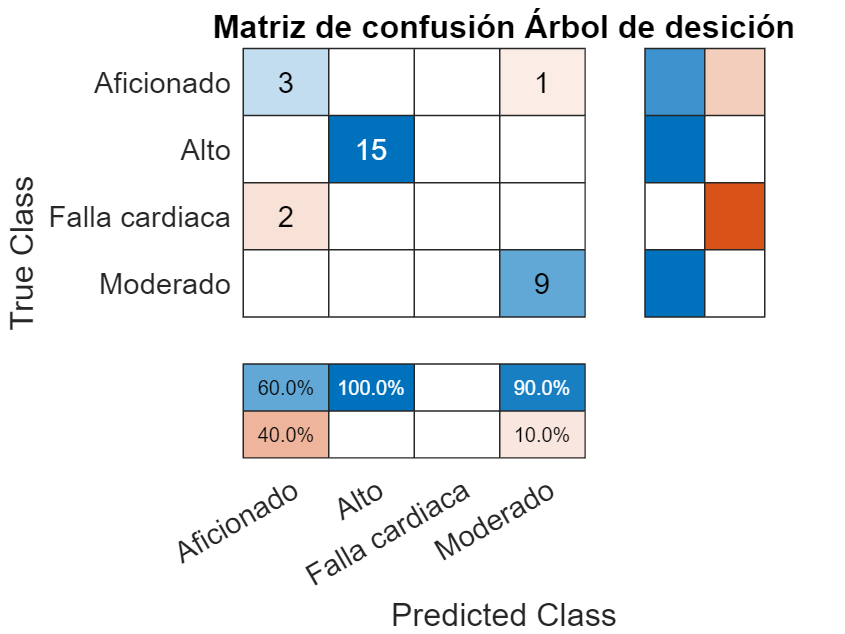

confusionchart(clasesPr,result,'ColumnSummary','column-normalized','RowSummary','row-normalized','Title','Matriz de confusión Árbol de desición')

# Bosques de desición

100 arboles

bosq=TreeBagger(100,dataEntr,clasesEntr)

bosq =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:               [70x3]
                    Training Y:               [70x1]
                        Method:       classification
                 NumPredictors:                    3
         NumPredictorsToSample:                    2
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    0
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:    'Aficionado'          'Alto' 'Falla cardiaca'      'Moderado'

  Properties, Methods


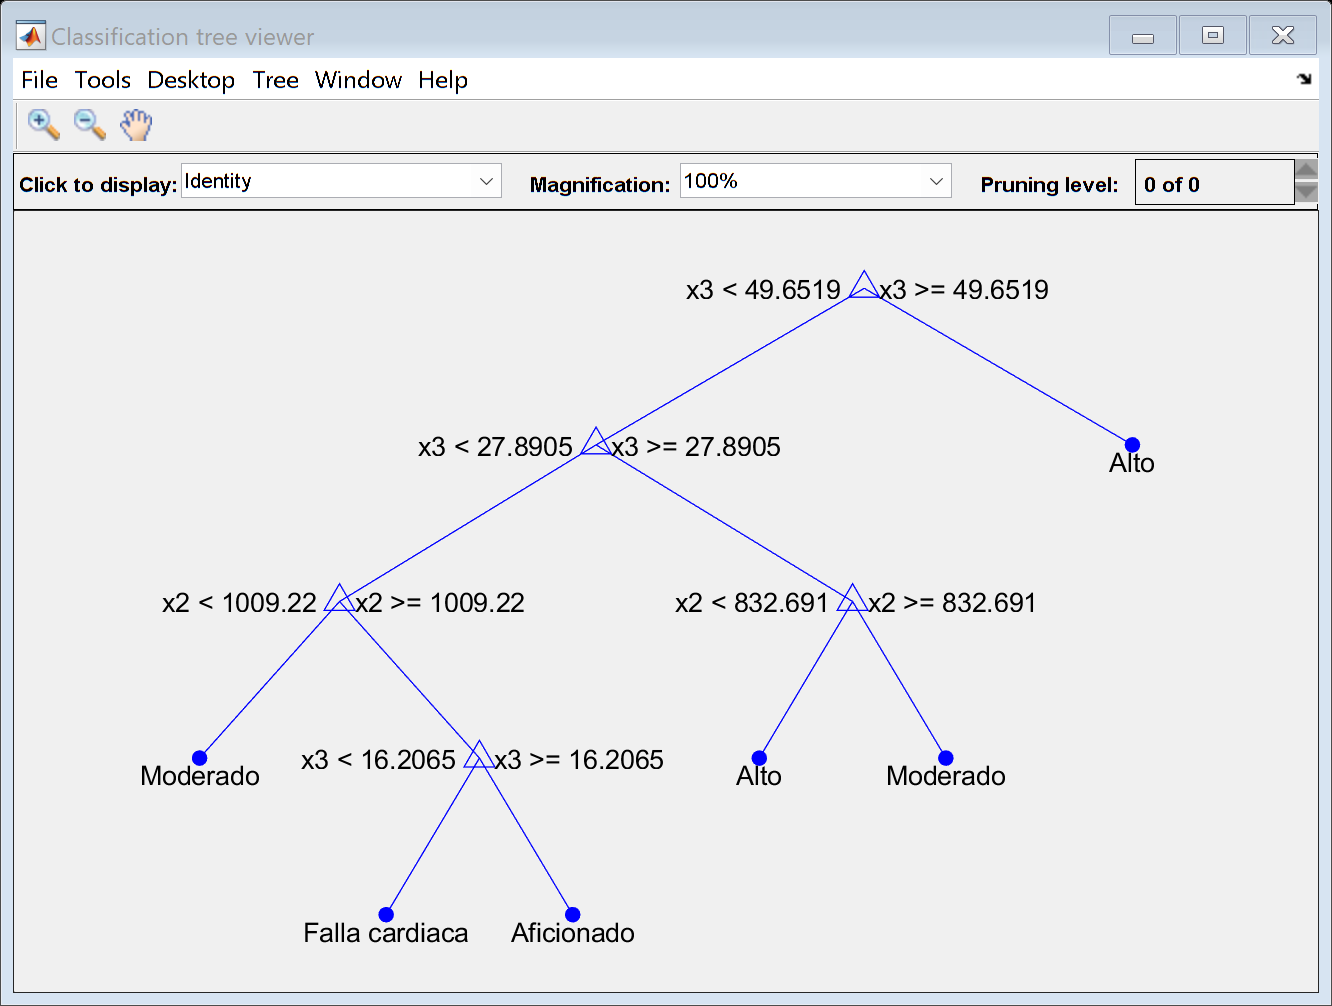

view(bosq.Trees{58},'Mode','graph')

resu=predict(bosq,dataPr);
resu

resu = 30×1 cell array
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Aficionado'    }
    {'Alto'          }
    {'Aficionado'    }
    {'Aficionado'    }
    {'Falla cardiaca'}
    {'Falla cardiaca'}


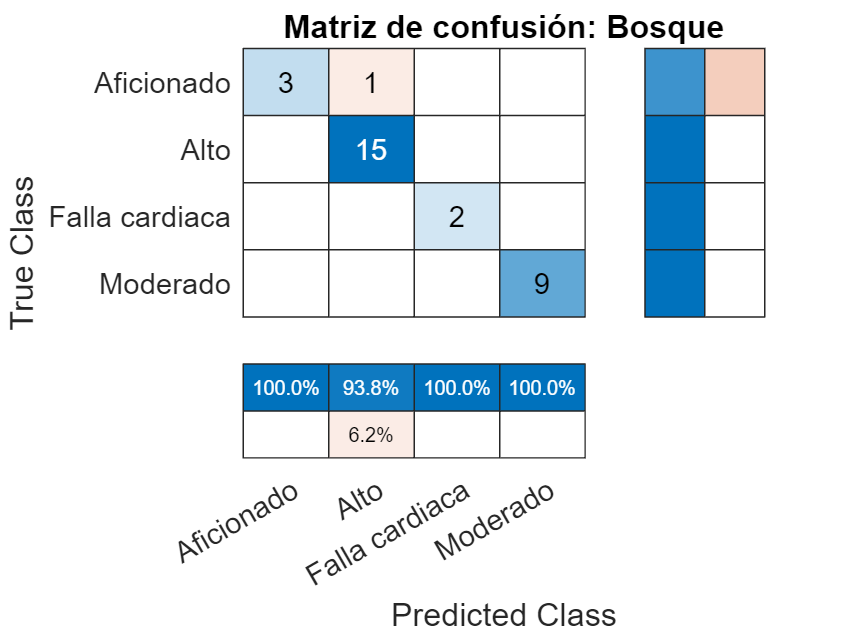

confusionchart(clasesPr,resu,'ColumnSummary','column-normalized','RowSummary','row-normalized','Title','Matriz de confusión: Bosque')

%confusionchart(clasesPr,resu)

10000 arboles

bosq1=TreeBagger(10000,dataEntr,clasesEntr)

bosq1 =   TreeBagger
Ensemble with 10000 bagged decision trees:
                    Training X:               [70x3]
                    Training Y:               [70x1]
                        Method:       classification
                 NumPredictors:                    3
         NumPredictorsToSample:                    2
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    0
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:    'Aficionado'          'Alto' 'Falla cardiaca'      'Moderado'

  Properties, Methods


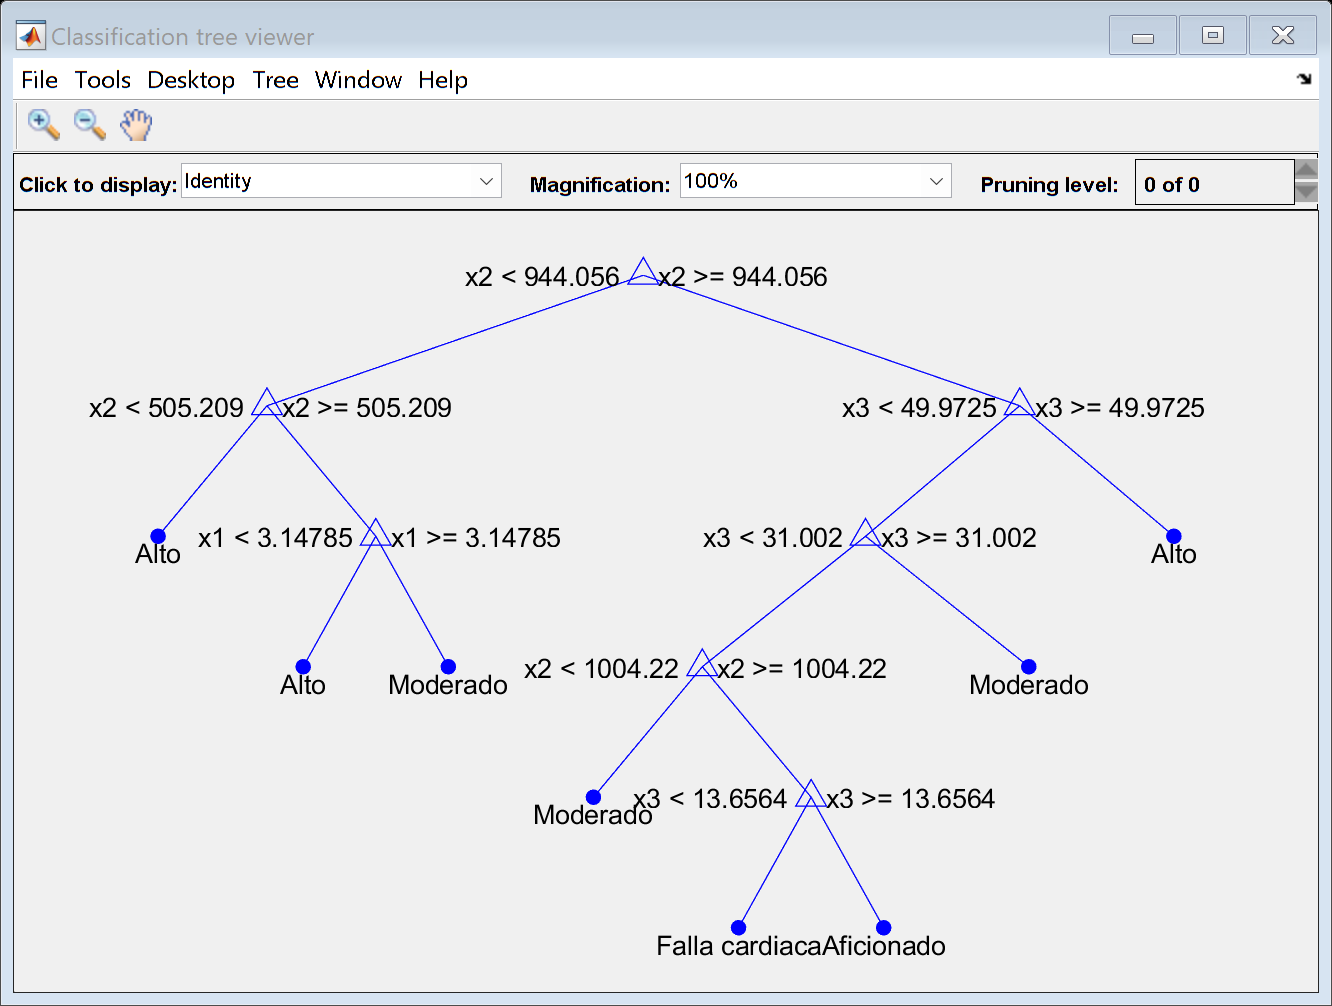

view(bosq1.Trees{58},'Mode','graph')

res=predict(bosq1,dataPr);
res

res = 30×1 cell array
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Alto'          }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Moderado'      }
    {'Aficionado'    }
    {'Alto'          }
    {'Aficionado'    }
    {'Aficionado'    }
    {'Falla cardiaca'}
    {'Falla cardiaca'}


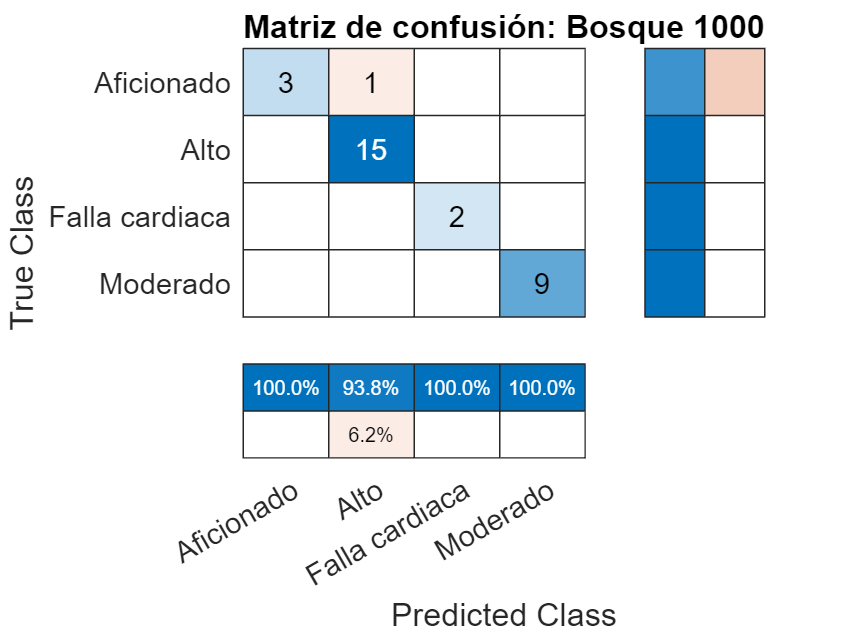

confusionchart(clasesPr,res,'ColumnSummary','column-normalized','RowSummary','row-normalized','Title','Matriz de confusión: Bosque 10000')